# **Matlab Live Tutorial**

Below, you will find a quick tutorial to view the electrophysiology and behavioral data which relates to:

- Paper: [https://doi.org/10.1038/s41598-025-07380-0](https://doi.org/10.1038/s41598-025-07380-0)

- Dataset: [](https://doi.org/10.63884/ndic.2025.jyxfer8m)

## Download NDI

In order to view the dataset, you will need access to the NDI platform. Follow the instructions found at [https://vh-lab.github.io/NDI-matlab/NDI-matlab/installation/](https://vh-lab.github.io/NDI-matlab/NDI-matlab/installation/) to download NDI and gain access to the suite of tools we have created!

## Import the NDI dataset

Define the dataset path and id.

% Choose the folder where the dataset is (or will be) stored
% dataPath = [userpath filesep 'Datasets']; % (e.g. /Users/myusername/Documents/MATLAB/Datasets)
% cloudDatasetId = '67f723d574f5f79c6062389d';
dataPath = fullfile(userpath,'data','hunsberger'); % (e.g. /Users/myusername/Documents/MATLAB/Datasets)
cloudDatasetId = 'hunsberger_2025';
datasetPath = fullfile(dataPath,cloudDatasetId);

### Download or load the NDI dataset 

The first time you try to access the data, it needs to be downloaded from NDI-cloud. This may take a few minutes. Once you have the dataset downloaded, every other time you examine the data you can just load it.

if isfolder(datasetPath)
    % Load if already downloaded
    dataset = ndi.dataset.dir(datasetPath);
else
    % Download
    if ~isfolder(dataPath), mkdir(dataPath); end
    dataset = ndi.cloud.downloadDataset(cloudDatasetId,dataPath);
end

### Retrieve the NDI session

A dataset can have multiple sessions, but this dataset has only one. We must retrieve it in order to access the associated data and metadata.

% Retrieve the session from this dataset
[session_ref_list,session_list] = dataset.session_list();
session = dataset.open_session(session_list{1});

## View subjects, treatments, and measurements

### View subject summary table

Each individual animal is referred to as a **subject** and has a unique alphanumeric SubjectDocumentIdentifier along with a SubjectLocalIdentifier which contains references to the animal's species, strain, id, and box number. Our database contains documents which store metadata about each **subject** including their species, strain, genetic strain type, and biological sex which are linked to well-defined ontologies. Additionally, metadata about any **treatments **or** measurments** that a **subject** received such as drug injections, date of birth, or weight are stored. A summary table showing the metadata for each **subject** can be viewed below.

% View summary table of all subject metadata
subjectSummary = ndi.fun.docTable.subject(dataset)

subjectSummary = 117×20 table
          SessionDocumentIdentifier                SubjectDocumentIdentifier                                  SubjectLocalIdentifier                                       StrainName                  StrainOntology                                        BackgroundStrainName                                           BackgroundStrainOntology         GeneticStrainTypeName      SpeciesName         SpeciesOntology      BiologicalSexName    BiologicalSexOntology    BiologicEntityBirthDate    BodyWeight    DrugTreatmentLocationOntology    DrugTreatmentLocationName    DrugTreatmentMixtureName    DrugTreatmentMixtureQuantity    DrugTreatmentMixtureOntology</

#### Filter subjects

We have created tools to filter a table by its values. Try finding **subjects** matching a given criterion.

Examples:

- `columnName = StrainName                     dataValue = eYFP`

- `columnName = DrugTreatmentMixtureName       dataValue = saline`

% Search for subjects
columnNamesSubject = subjectSummary.Properties.VariableNames;
columnName = columnNamesSubject(17);
dataValue = "saline";
rowInd = ndi.fun.table.identifyMatchingRows(subjectSummary,...
    columnName{1},dataValue,'stringMatch','contains');
filteredSubjects = subjectSummary(rowInd,:)

filteredSubjects = 71×20 table
          SessionDocumentIdentifier                SubjectDocumentIdentifier                                  SubjectLocalIdentifier                                        StrainName                  StrainOntology                                        BackgroundStrainName                                           BackgroundStrainOntology         GeneticStrainTypeName      SpeciesName         SpeciesOntology      BiologicalSexName    BiologicalSexOntology    BiologicEntityBirthDate    BodyWeight    DrugTreatmentLocationOntology    DrugTreatmentLocationName    DrugTreatmentMixtureName    DrugTreatmentMixtureQuantity    DrugTreatmentMixtureOntology

## Retrieve data tables

### Get contextual fear conditioning data

% Get contextual fear conditioning documents/table
query = ndi.query('ontologyTableRow.names','contains_string','contextual fear conditioning');
docsCFC = session.database_search(query);
tableCFC = ndi.fun.doc.ontologyTableRowDoc2Table(docsCFC); 

% Add subject metadata
tableCFC = ndi.fun.table.join({tableCFC{1},subjectSummary})

tableCFC = 936×27 table
                           SubjectLocalIdentifier                                  SubjectDocumentIdentifier          ExperimentTrialExecutionTimestamp    Age_Days    ContextualFearConditioning_BlockType    ContextualFearConditioning_BlockMinute    ContextualFearConditioning_TimeFreezing    ContextualFearConditioning_BlockDuration    ContextualFearConditioning_PercentTimeFreezing          SessionDocumentIdentifier                     StrainName                  StrainOntology                                        BackgroundStrainName                                           BackgroundStrainOntology         GeneticStrainTypeName      SpeciesName         SpeciesOntology      

### Get cell count data

% Get cell count documents/table
query = ndi.query('ontologyTableRow.names','contains_string','Cell Count');
docsCells = session.database_search(query);
tableCells = ndi.fun.doc.ontologyTableRowDoc2Table(docsCells); 

% Add subject metadata
tableCells = ndi.fun.table.join({tableCells{1},subjectSummary})

tableCells = 120×26 table
                           SubjectLocalIdentifier                                  SubjectDocumentIdentifier                           BrainRegionName                      BrainRegionOntologyIdentifier    EYFPAverageCellCount    C_fosAverageCellCount    EYFPEngramAverageCellCount    C_FosEngramAverageCellCount          SessionDocumentIdentifier                     StrainName                  StrainOntology                                        BackgroundStrainName                                           BackgroundStrainOntology         GeneticStrainTypeName      SpeciesName         SpeciesOntology      BiologicalSexName    BiologicalSexOntology    B

### Retrieve variable definitions

% Get list of all variables
[fullNames,shortNames,ontologyNodes] = ndi.fun.doc.ontologyTableRowVars(session);

Select a variable to view it's definition.

% Look up the variable in the ontology
variableName = fullNames(11);
termIndex = strcmpi(fullNames,variableName{1});
termID = ontologyNodes{termIndex};
[id,name,prefix,definition,synonyms,shortName] = ...
    ndi.ontology.lookup(termID);

% Display the variable's id, name, definition, and short name
termInfo = cell2table({id,name,definition,shortName}',...
    'RowNames',{'id','name','definition','shortName'},...
    'VariableNames',{'value'})

termInfo = 4×1 table
                                           value                         
                  _______________________________________________________

    id            {'EMPTY:00000283'                                     }
    name          {'contextual fear conditioning: percent time freezing'}
    definition    {0×0 char                                             }
    shortName     {'ContextualFearConditioning_PercentTimeFreezing'     }


## Plot data

### Plot cell count data

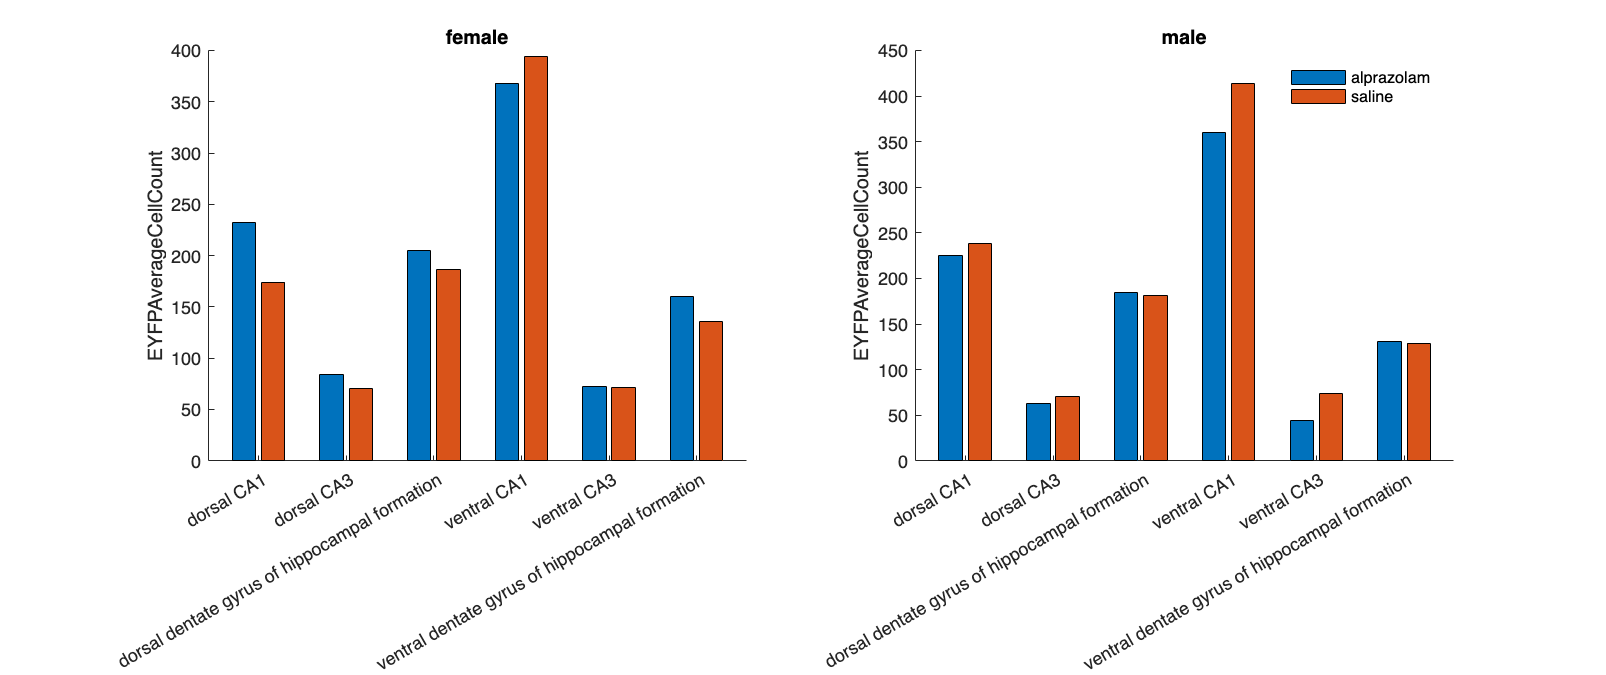

% Define grouping and plotting variables
plottingVariable = 'EYFPAverageCellCount';
groupingVariables = {'BiologicalSexName','BrainRegionName','DrugTreatmentMixtureName'};

% Plot data
fig = ndi.fun.plot.bar3(tableCells,groupingVariables,plottingVariable);
fig.Position(3) = 1000;

### Plot contextual fear conditioning data

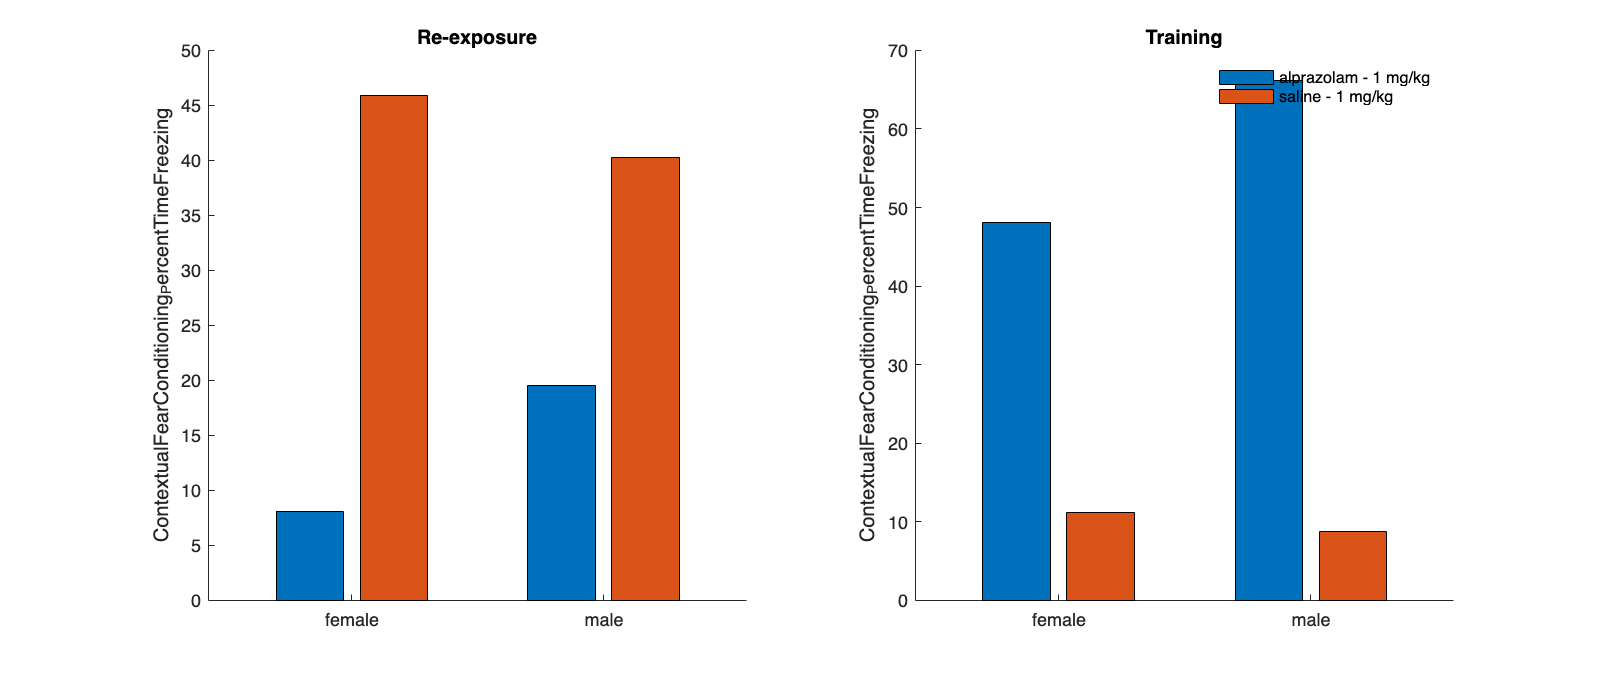

% Combine drug treatment name and quantity (for easy sorting)
tableCFC.DrugTreatmentMixture = cellfun(@(a,b) strjoin({a,b},' - '), ...
    tableCFC.DrugTreatmentMixtureName,tableCFC.DrugTreatmentMixtureQuantity,'UniformOutput',false);

% Define grouping and plotting variables
plottingVariable = 'ContextualFearConditioning_PercentTimeFreezing';
groupingVariables = {'ContextualFearConditioning_BlockType','BiologicalSexName','DrugTreatmentMixture'};

% Plot data
indCFC = ismember(tableCFC{:,'DrugTreatmentMixtureName'},{'saline','alprazolam'});
fig = ndi.fun.plot.bar3(tableCFC(indCFC,:),groupingVariables,plottingVariable);
fig.Position(3) = 1000;

### Plot state-dependent contextual fear conditioning data

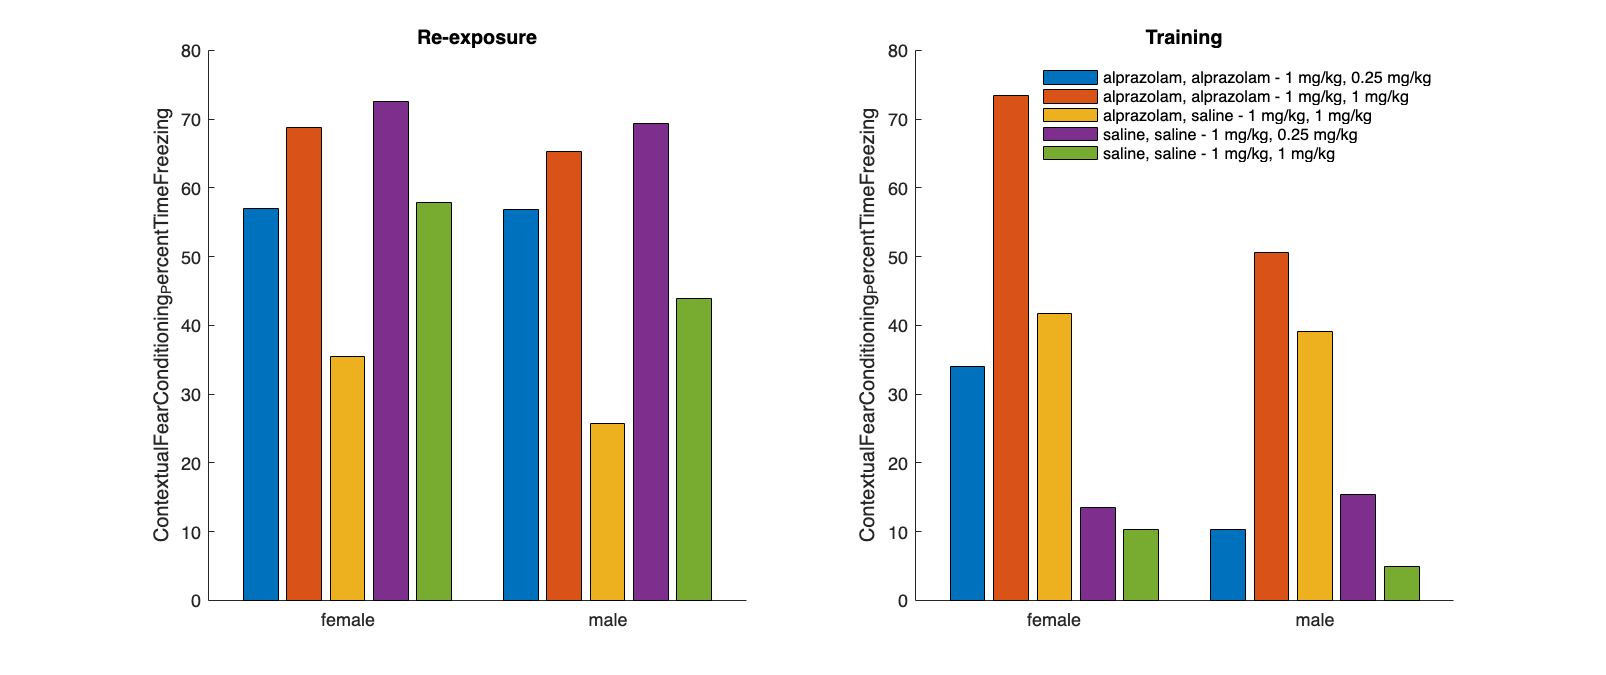

% Define grouping and plotting variables
plottingVariable = 'ContextualFearConditioning_PercentTimeFreezing';
groupingVariables = {'ContextualFearConditioning_BlockType','BiologicalSexName','DrugTreatmentMixture'};

% Plot data
fig = ndi.fun.plot.bar3(tableCFC(~indCFC,:),groupingVariables,plottingVariable);
fig.Position(3) = 1000;